mu1 = 0;
mu2 = 0;
mu = [mu1 mu2];

sigma1 = 3;
sigma2 = 1;
rho = 0.99;

Cx = [sigma1^2 rho*sigma1*sigma2; ...
    rho*sigma1*sigma2 sigma2^2];

x1 = 0;
x2 = 0;

mvncdf([x1 x2],mu, Cx) % mvn = multivariate normal

ans = 0.4775

mvnpdf([x1 x2],mu, Cx) % mvn = multivariate normal

ans = 0.3761

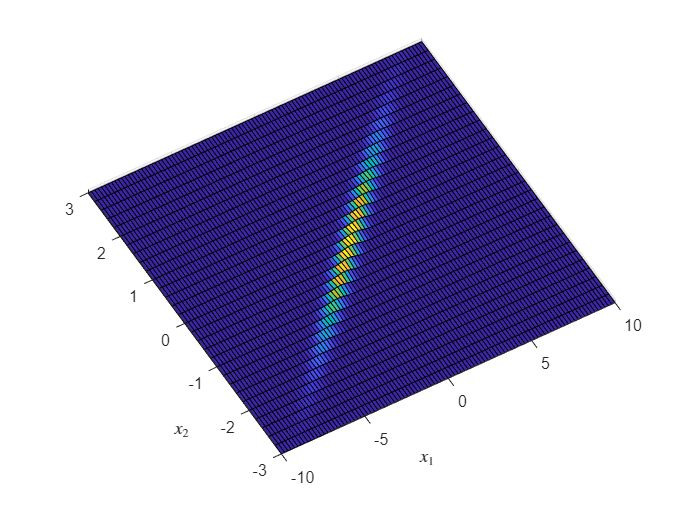

%% PDF
x1 = -10:.2:10; x2 = -3:.2:3;
[X1, X2] = meshgrid(x1, x2);
F = mvnpdf([X1(:) X2(:)], mu, Cx);
F = reshape(F, length(x2), length(x1));

figure(2)
surf(x1,x2,F);
xlabel('$x_1$','Interpreter','Latex');
ylabel('$x_2$','Interpreter','Latex');
zlabel('$f_{\bf X}({\bf x})$','Interpreter','Latex');

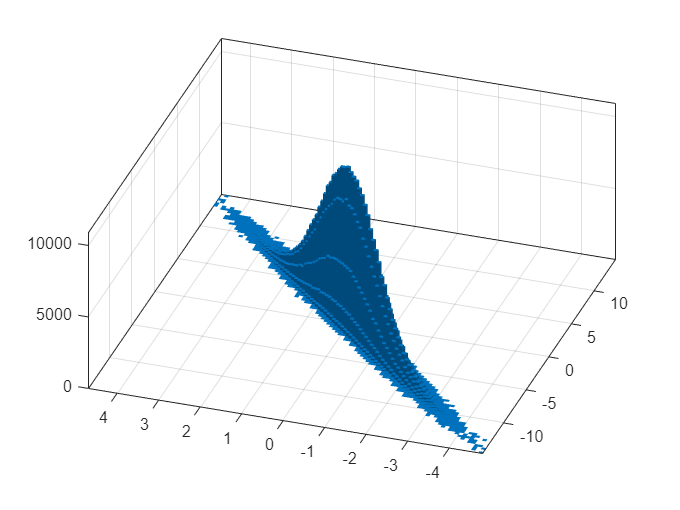

X = mvnrnd(mu, Cx, 1e6);
histogram2( X(:,1), X(:,2) )